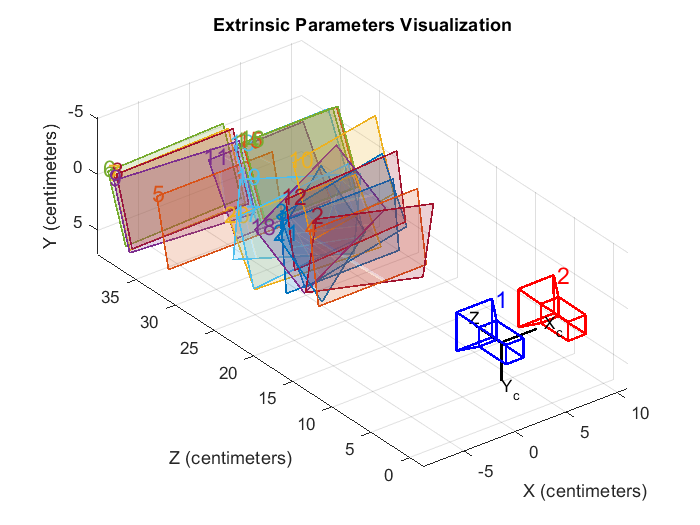

load('st_param3.mat')

% Visualize camera extrinsics.
showExtrinsics(stereoParams);

I1 = imread('imageR1.png');
I2 = imread('imageL1.png');

%faceDetector = vision.CascadeObjectDetector;
%face1 = faceDetector(I1)
%face2 = faceDetector(I2)
%------------------------------------
% Read the image into an array.

I1 = undistortImage(I1,stereoParams.CameraParameters1);
I2 = undistortImage(I2,stereoParams.CameraParameters2);

%face1 = [83 62 214-70 143-70]
%face2 = [154 67 285-70 146-70]

%center1 = face1(1:2) + face1(3:4)/2
%center2 = face2(1:2) + face2(3:4)/2

center1 = [133 48]

center1 =    133    48


center2 = [251 52]

center2 =    251    52



obj1 =  [center1 2]

obj1 =    133    48     2


obj2 = [center2 2]

obj2 =    251    52     2


point3d = triangulate(center1, center2, stereoParams)

point3d =     2.1277    3.8463  -14.7117


%distanceInMeters = norm(point3d)
distanceInCm = norm(point3d)

distanceInCm = 15.3543

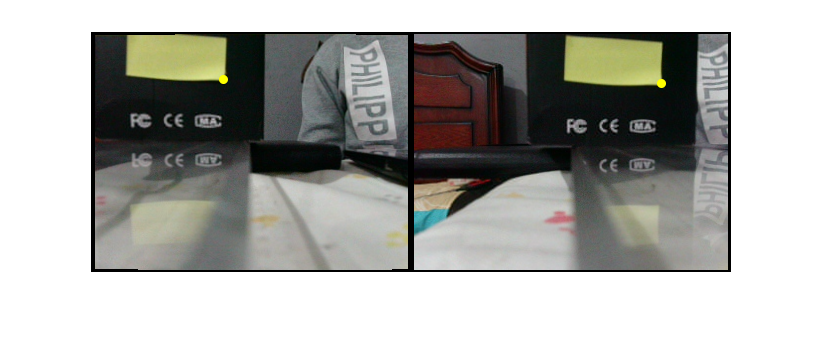

%distanceAsString = sprintf('%0.2f mm', distanceInMeters);
I1 = insertShape(I1,'Circle',obj1,'LineWidth',5);
I2 = insertShape(I2,'Circle',obj2,'LineWidth',5);
 
imshowpair(I1, I2, 'montage');